# **Duggoff Tire model**

# **+**

# **Longitudinal Model, for vehicle speed profile**

# **+**

# **Lateral Model for vehicle yaw rate and side slip**

**Simulink Simulations Report**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Autonomy in Vehicles ECE 5553  | Ohio State University | 2/20/2023

with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc

clc; clear; close all

% Add the Simulink models needed to the current path 
folder_path = 'simulink_models'; % specify the folder name
addpath(genpath(folder_path)); % add the folder and all subfolders to the path

## Contents 

A. Tire force model

    Dugoff tire force model

    longitudinal force vs longitudinal slip

    longitudinal force vs side slip angle for slip values s = 0.1,0.2,0.3,0.4,0.5

    tire force ellipse

B. Longitudinal vehicle model

    Nonlinear longitudinal vehicle model in Simulink

    Coast down profile

    Full brake profile

    Headwind Simulation

    Road Slope Simulation

C. Lateral vehicle model

    Yaw velocity gain

    Linear vs nonlinear vehicle model

    Yaw rate comparison

    Side slip angle comparison

# A. The Duffoff Tire Model

Duggoff Model

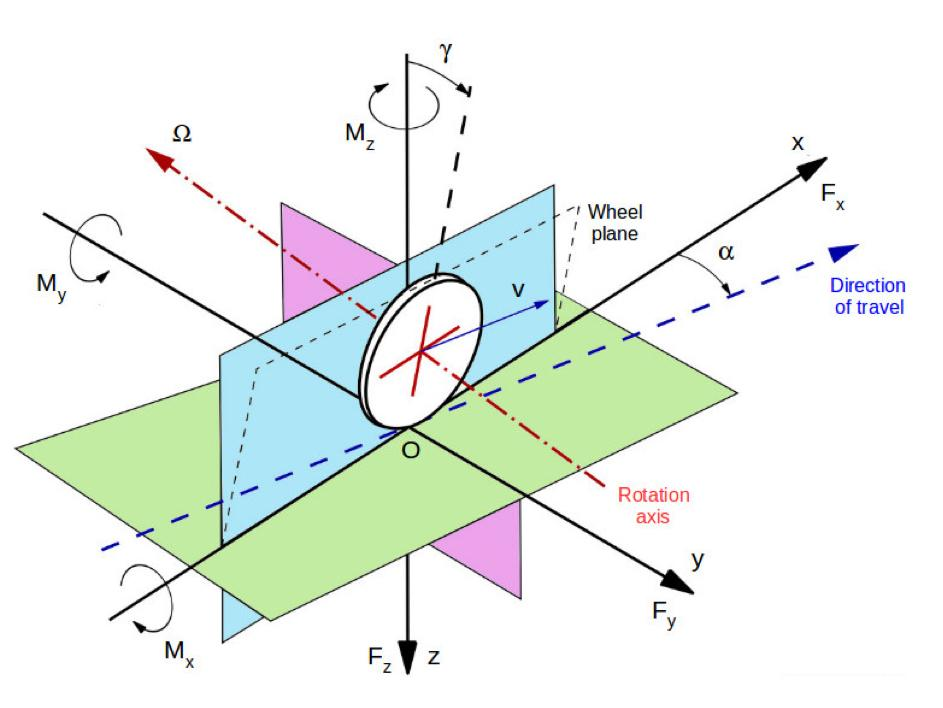

Tire Slip, s

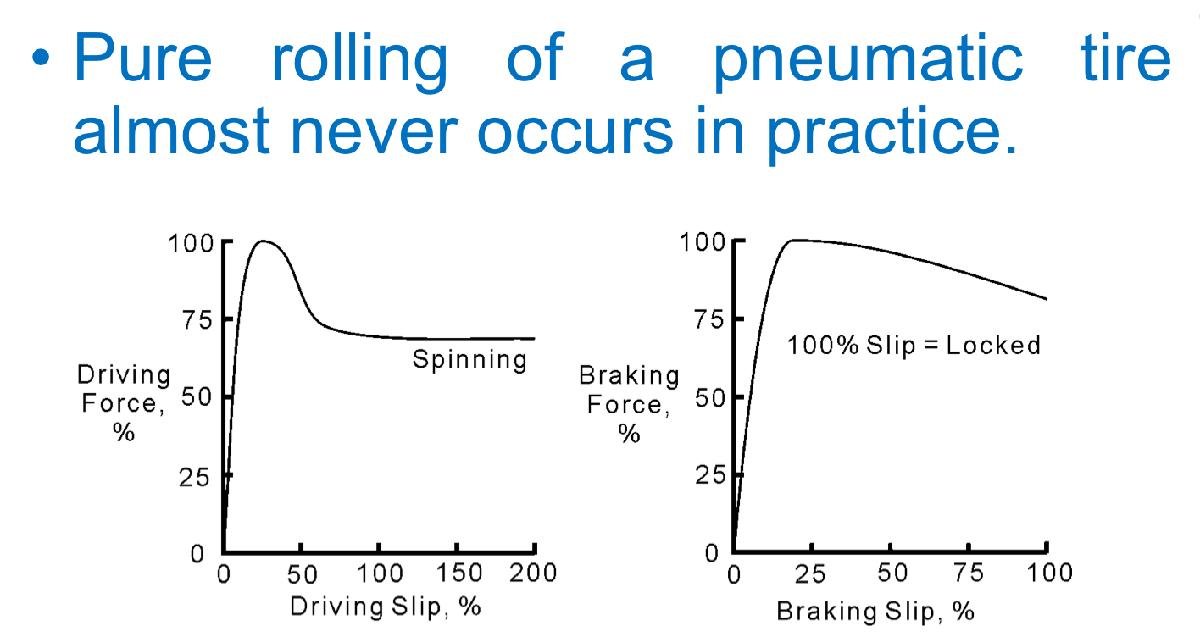

**SIMULINK Diagram**

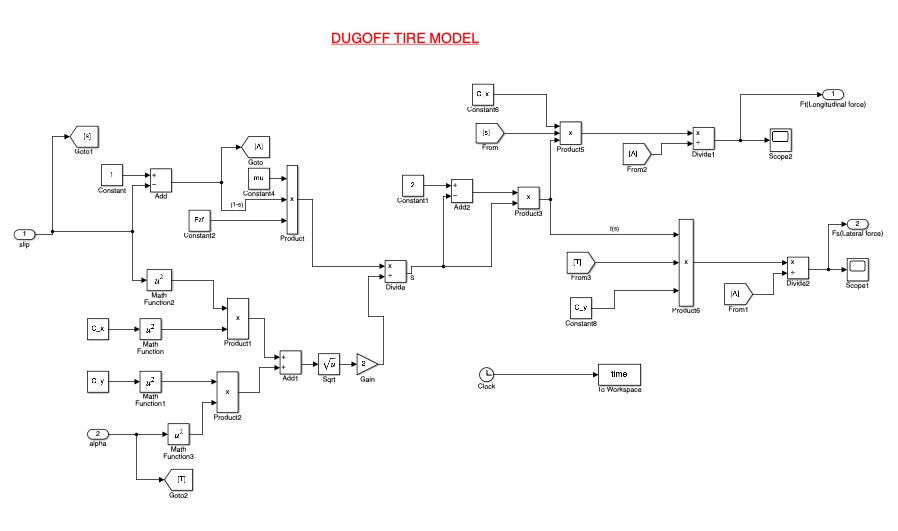

#### Model Parameters can be found and described in "getTireParameters()" in the functions section 

%[M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters();

### 1. Tire forces vs slip ratio

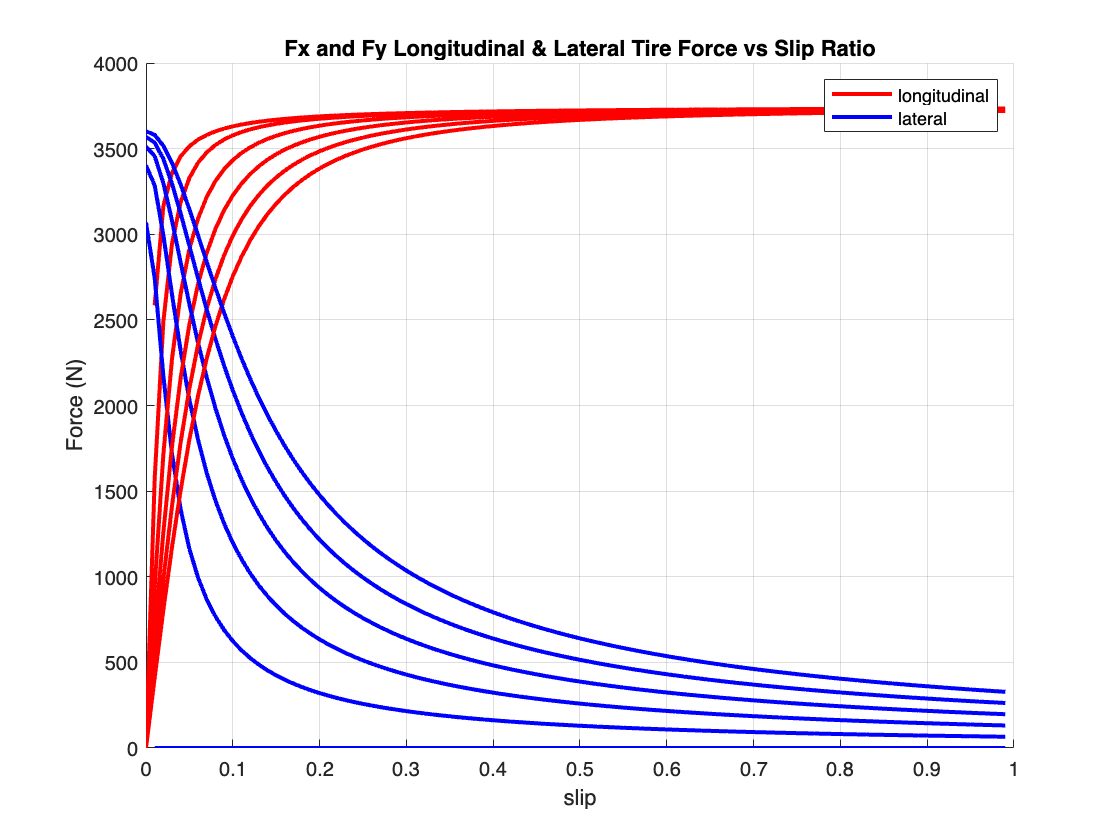

%Alpha is held constant
[M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters();

s=[0:0.01:1]';
figure, hold on
for alpha = (0:2:10)*pi/180
    %at = [a*ones(length(time))',time];
    sim('tire_model');
    %v1 = saveVehicle(Fx,Fy,s,a); plot(v1.Fx,v1.s); 
    plot(s,Fx,'r','linewidth',2)
    plot(s,Fy,'b','linewidth',2)
end 
xlabel('slip'),ylabel('Force (N)'), title('Fx and Fy Longitudinal & Lateral Tire Force vs Slip Ratio'), grid on
legend('longitudinal','lateral')

Fx1 = Fx; Fy1 = Fy;

### 2. Tire Forces vs side slip angle

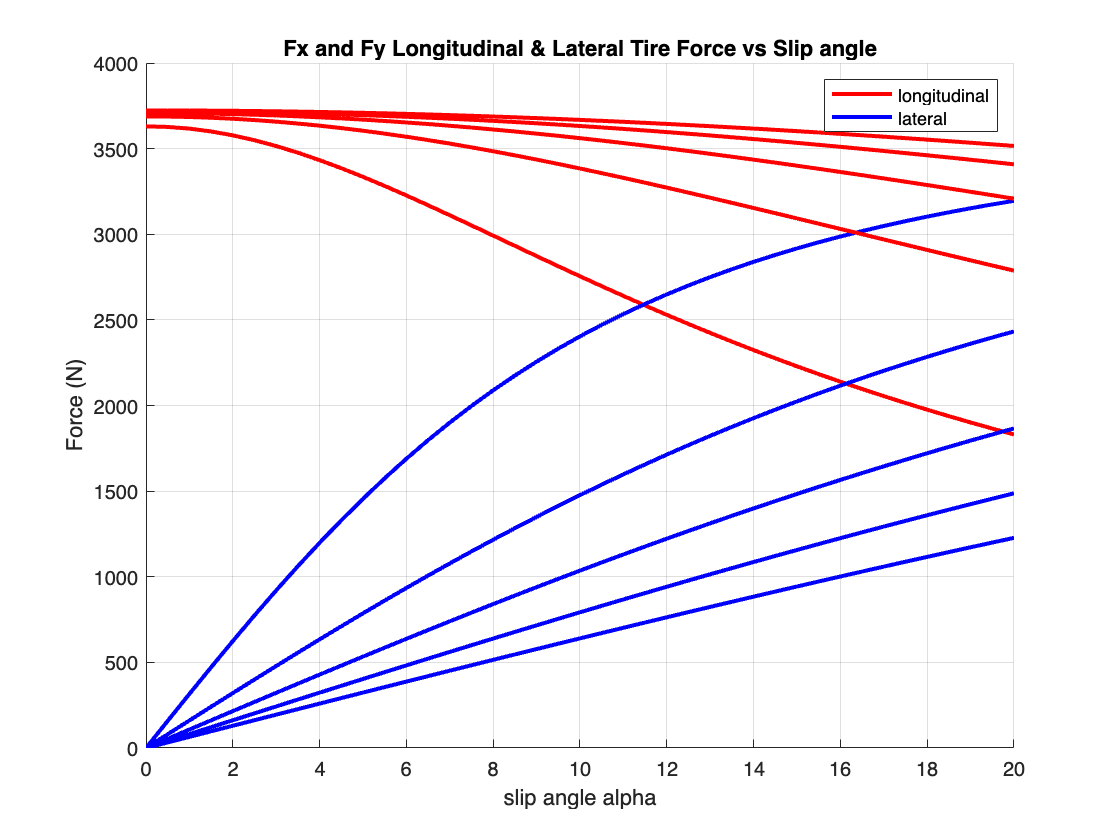

close all
%Alpha is held constant
[M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters();

alpha=[0:.5:20]'*pi/180;
figure, hold on
for s = (0.1:.1:0.5)
    %at = [a*ones(length(time))',time];
    sim('tire_model');
    %v1 = saveVehicle(Fx,Fy,s,a); plot(v1.Fx,v1.s); 
    plot(alpha*180/pi,Fx,'r','linewidth',2)
    plot(alpha*180/pi,Fy,'b','linewidth',2)
end 
xlabel('slip angle alpha'),ylabel('Force (N)'), title('Fx and Fy Longitudinal & Lateral Tire Force vs Slip angle'), grid on
legend('longitudinal','lateral')

Fx2 = Fx; Fy2 = Fy;

### 3. Force Ellipse

Demonstrating that Fx and Fy are inversely related

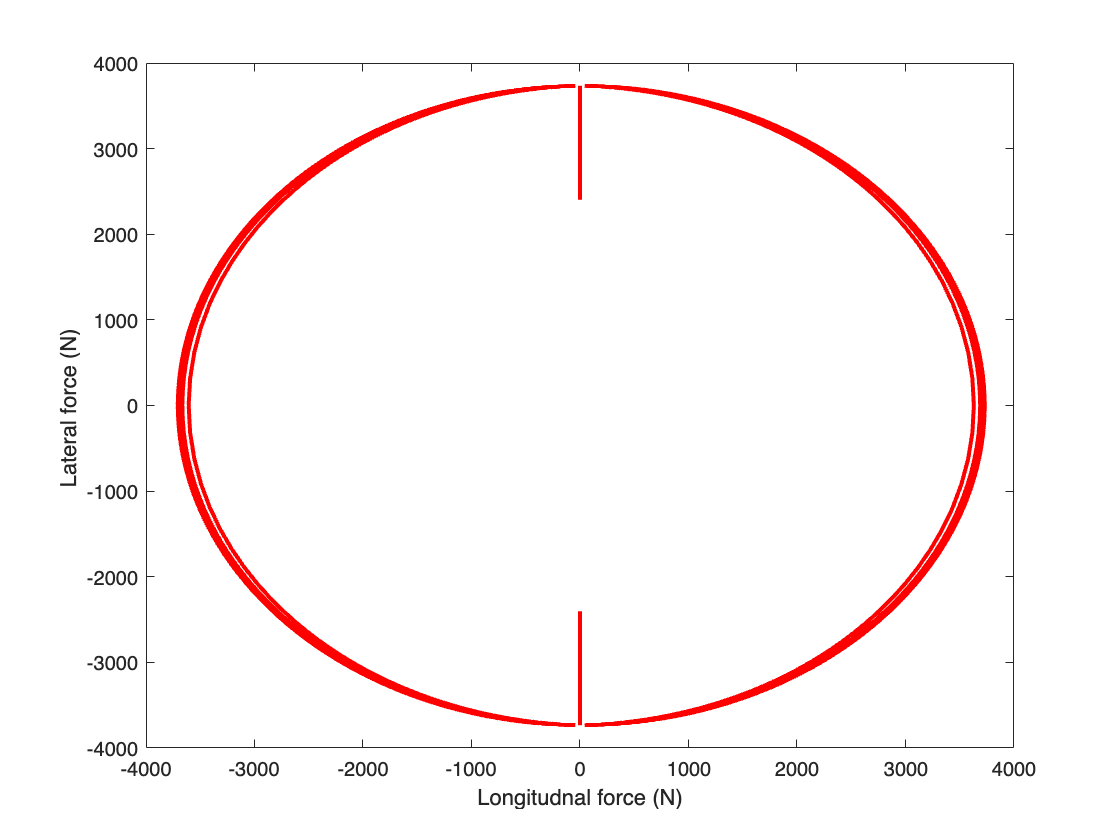

close all
figure
alpha = [-1000:1:1000]*pi/180;
for s = [-0.1 -0.2 -0.3 -0.4 -0.5 -0.6 -0.7 0 0.1 0.2 0.3 0.4 0.5 0.6 0.7]
    sim('tire_model');
    plot (Fx, Fy,'r','linewidth',2)
    hold on
    xlabel('Longitudnal force (N)');
    ylabel( 'Lateral force (N) ')
end

# B. Longitudinal Vehicle Model

# building off the tire force model above

#### Longitudinal Vehicle Model Top Level Diagram 

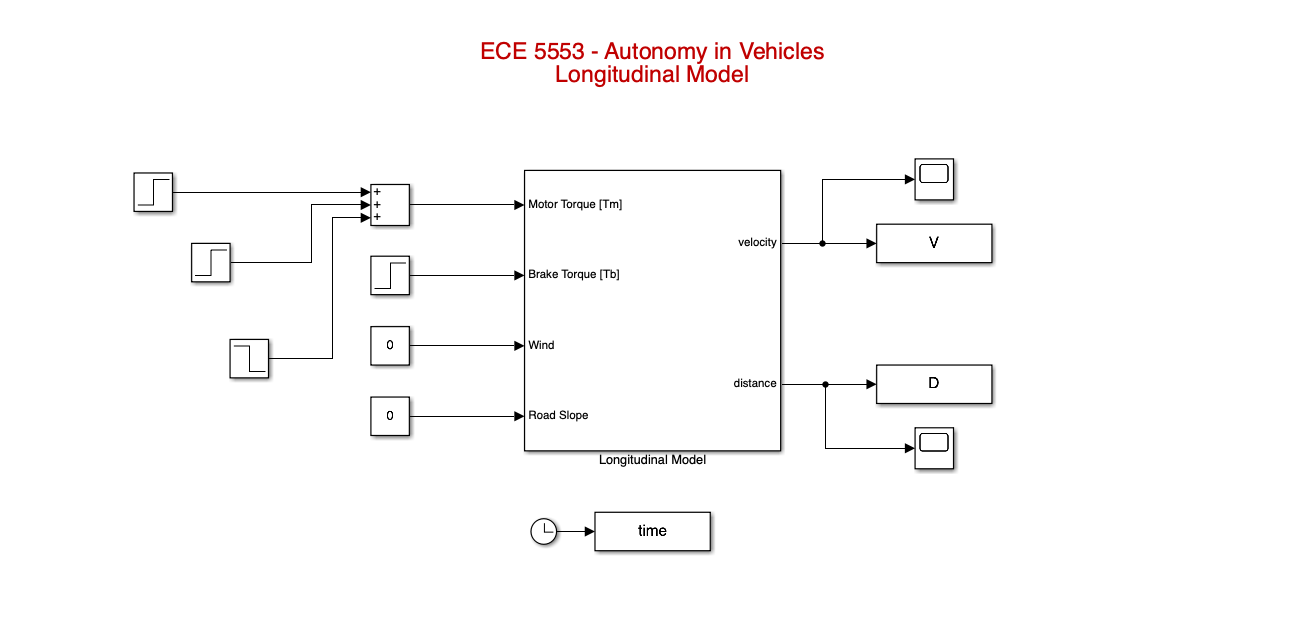

The step signals are added to create the desired motor torque commands in the following situations where the velocity over time is taken to be the output of the simulation

#### Vehicle Model Diagram

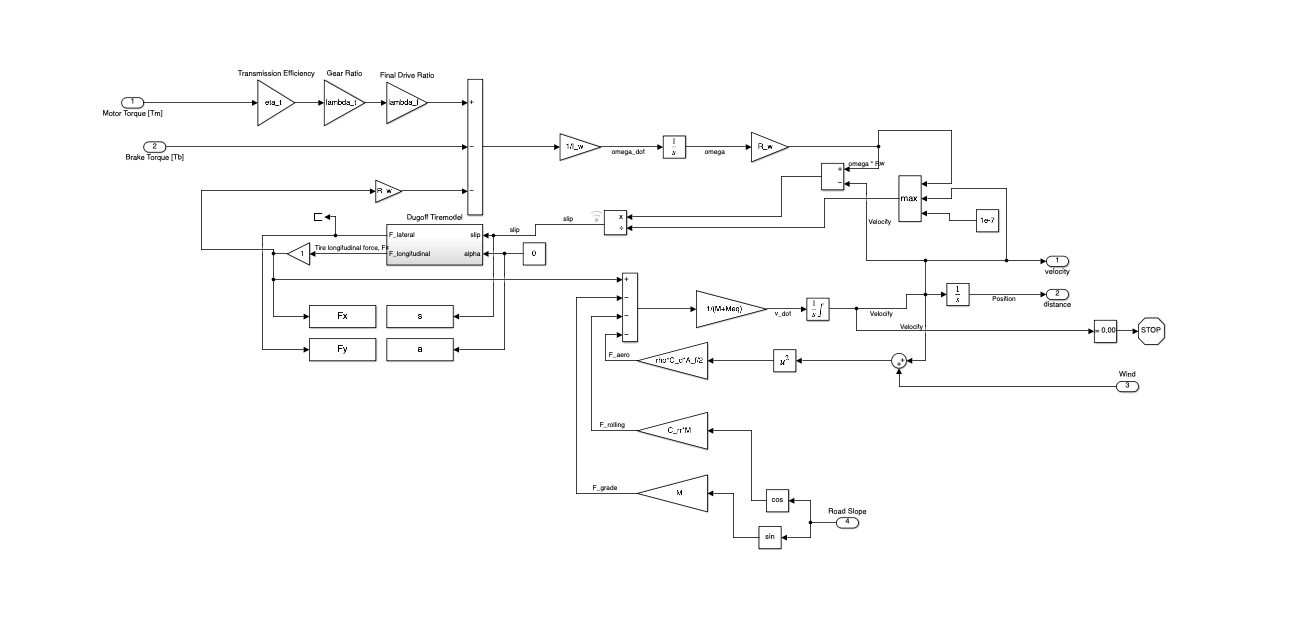

The duggoff tire model is the lowest level diagram which was reviewed in the previous section of this report

Overall, The model takes into account brake and motor torque commands where the vehicle moves straight only. The following sections will demonstrate simulation outputs for different scenarios. The Example numbers in the model suggest that the driver is pressing the gas pedal from time 0 to time 300 with a strength of 50 (motor torque command is 50). Next, at time 300, the driver presses the gas pedal harder (motor torque command is 100). Then, at time 400, the driver lets go of the gas pedal (motor torque command drops to 0) and simultaneously, the driver presses the brake (brake command increases from 0 to 100).

#### The example simulation numbers and veloctiy profile

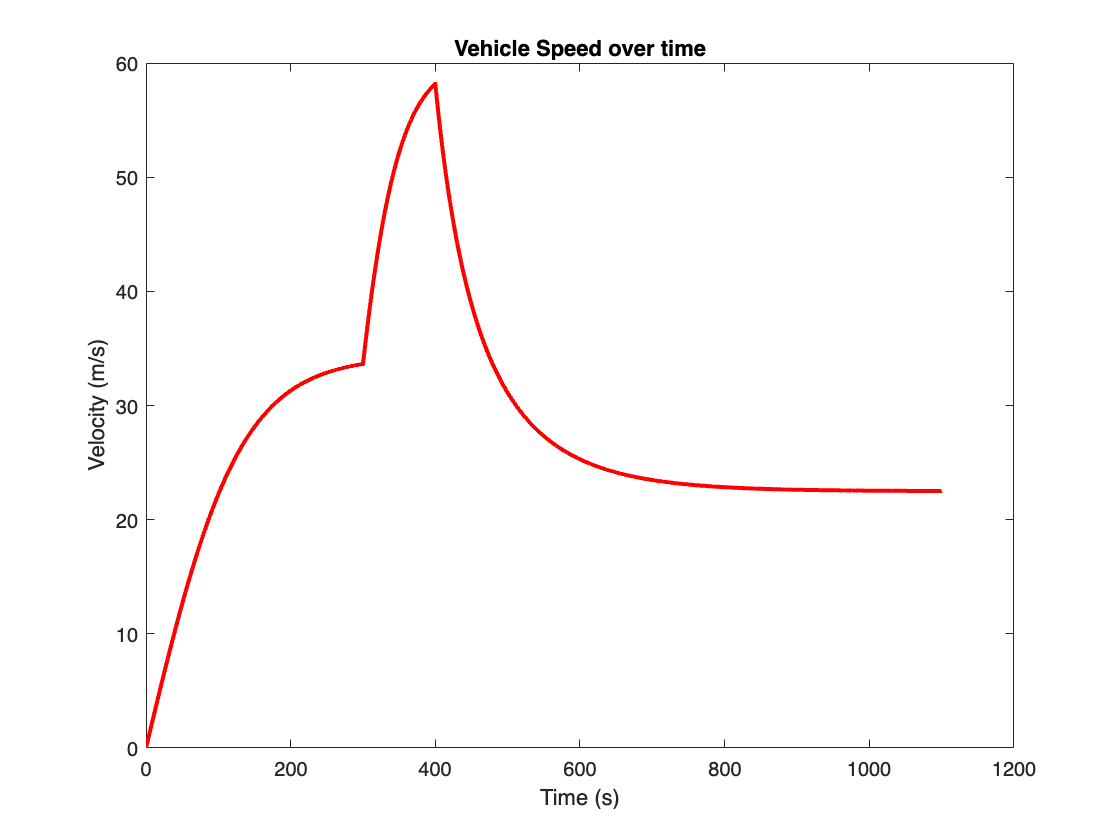

close all, figure

motorStart = 50;
motorStartTime = 0;

motorIncrease = 100;
motorIncreaseTime = 300; 

motorDecrease = 100;
motorDecreaseTime = 400;

brakeTime = 400;
breakStrength = 100;

headWindTime = 0;
headWind = 0;

roadSlopeTime = 0;
roadSlope = 0;

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')
plot(time,V,'r','linewidth',2), xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

#### Linear System Identification 

close all, figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 0;
motorDecreaseTime = 0;

brakeTime = 0;
breakStrength = 0;

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

#### Plotting V/(Motor Torque)

To model the experimental transfer function with a simpler model, ignoring engine dynamics

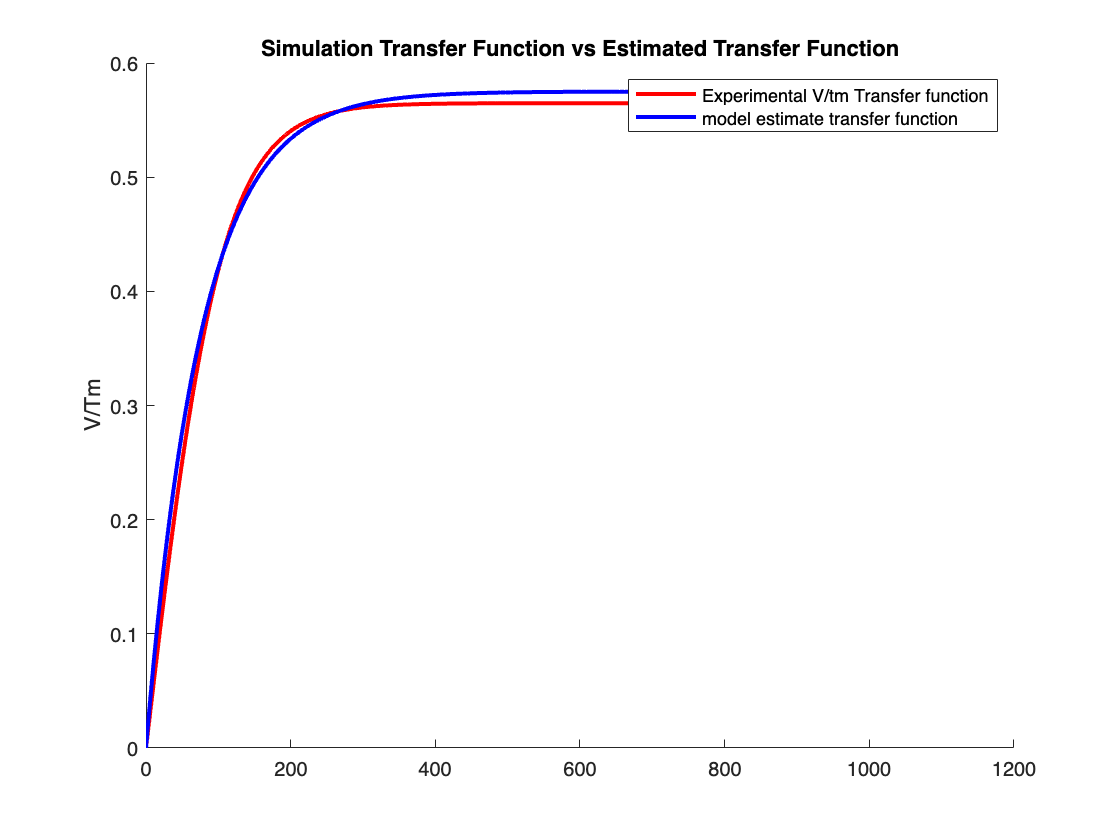

close all, figure, hold on
K = 0.575;
T = 76;   	
plot(time,V./Tm,'r','linewidth',2)

s = tf('s');
V_tf = K/ ( T*s + 1);

[h,g] = step(V_tf);
plot(g, squeeze(h), 'b','LineWidth',2)

legend('Experimental V/tm Transfer function','model estimate transfer function')
title('Simulation Transfer Function vs Estimated Transfer Function')
ylabel('V/Tm')

Find *K *and τ values from this simulated 				

response for the simple model *V/Tm *= *Ke^(*−τ*d*s) /  (*τ*s + 1) with τ*d *= 0 and compare the simulated output to this model

simplified V/Tm = K/(τ*s + 1)

#### Coast Down Simulation

Simulation scenario 3, step rise in motor torque, wait for speed to settle, then decrease motor torque to zero to record the coast down velocity profile. 

close all, figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 75;
motorDecreaseTime = 300;

brakeTime = 0;
breakStrength = 0;

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

#### Coast Down Response

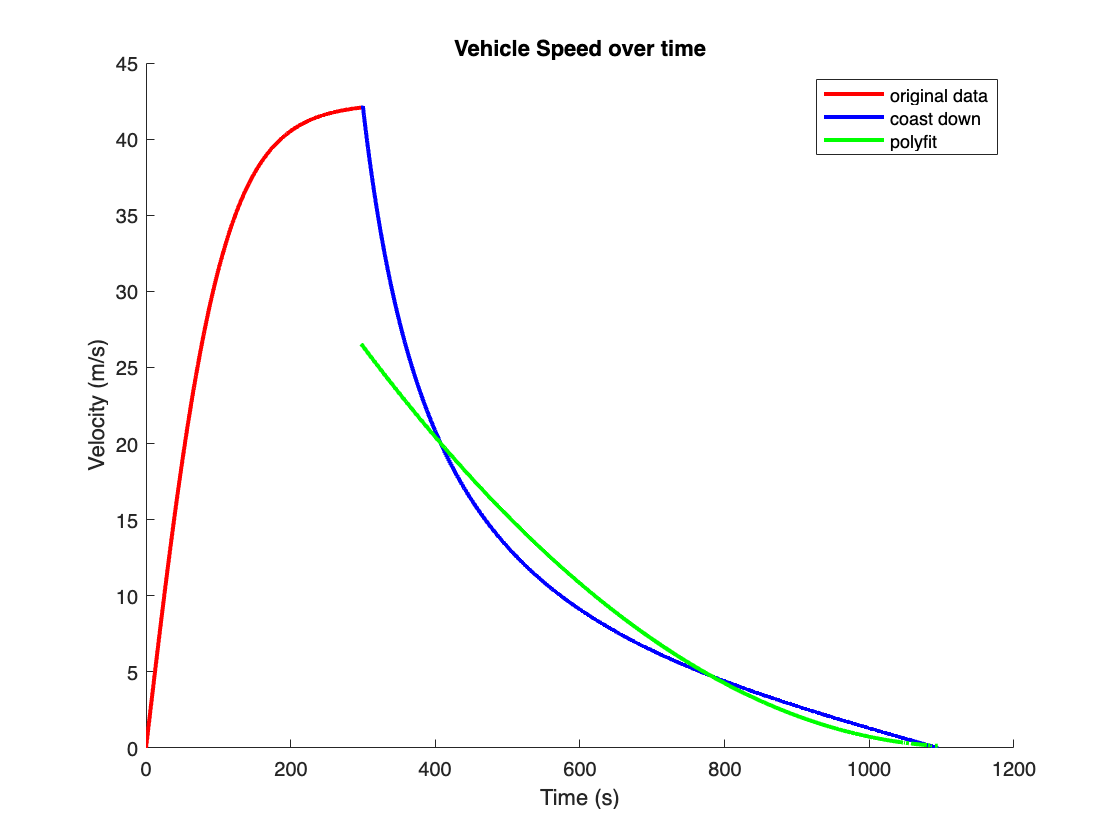

close all, figure
hold on
extractFrom = 108000;
len = length(time);
extractTo = len;
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:extractTo),V(extractFrom:extractTo),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('original data','coast down','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

The Polynomial Coefficients are

s = sprintf('y = (%.1f) x^2 + (%.1f) x + (%.1f)',p(1),p(2),p(3))

s = 'y = (0.0) x^2 + (-0.1) x + (48.8)'

#### Full Brake Simulation

Let Speed settle with a given Tm, then record the braking response

close all, figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 75;
motorDecreaseTime = 300;

brakeTime = 300;
breakStrength = 100;

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

#### Full Brake Response Plot	

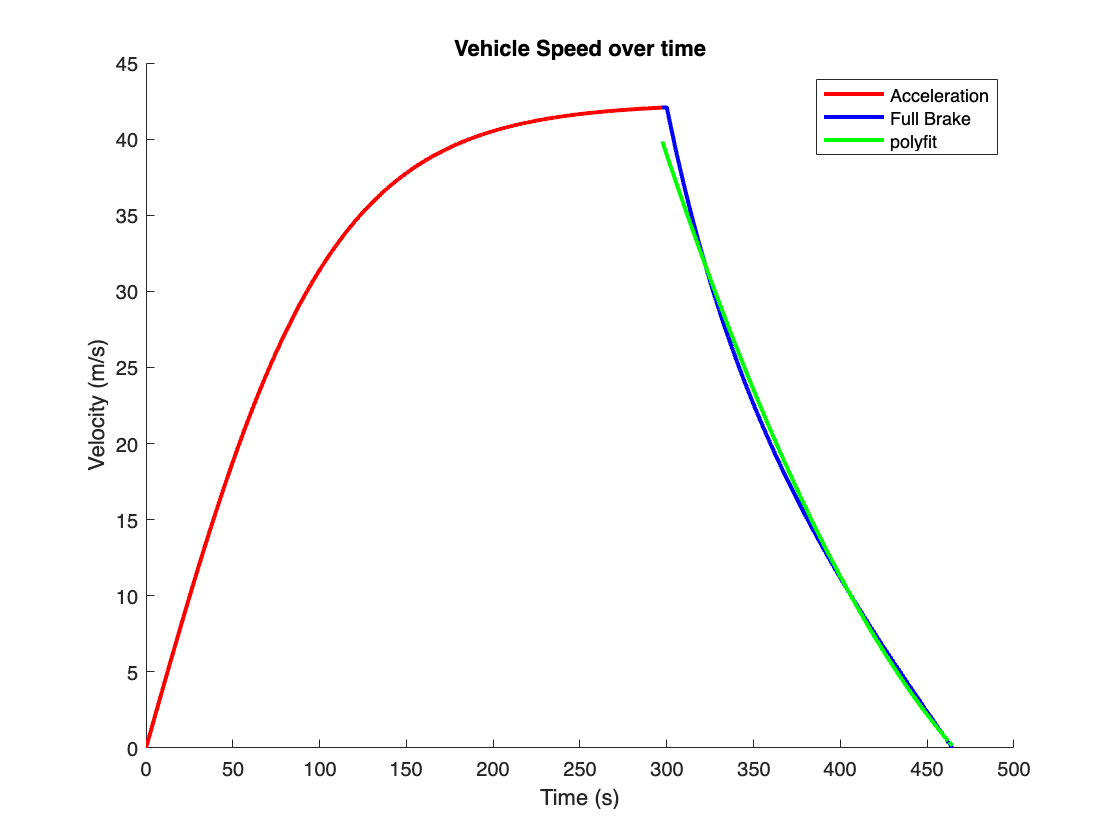

close all, figure
hold on
extractFrom = 108000;
len = length(time);
extractTo = len;
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:extractTo),V(extractFrom:extractTo),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('Acceleration','Full Brake','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

The Polynomial Coefficients are

s = sprintf('y = (%.1f) x^2 + (%.1f) x + (%.1f)',p(1),p(2),p(3))

s = 'y = (0.0) x^2 + (-0.7) x + (198.2)'

#### Headwind Simulation

Speed Settles, then headwind suddenly increases

close all, figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 0;
motorDecreaseTime = 0;

brakeTime = 0;
breakStrength = 0;

headWindTime = 300;
headWind = 10;

roadSlopeTime = 0;
roadSlope = 0;

% Headwind increases to 10 at time 300

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

#### Headwind Plotting

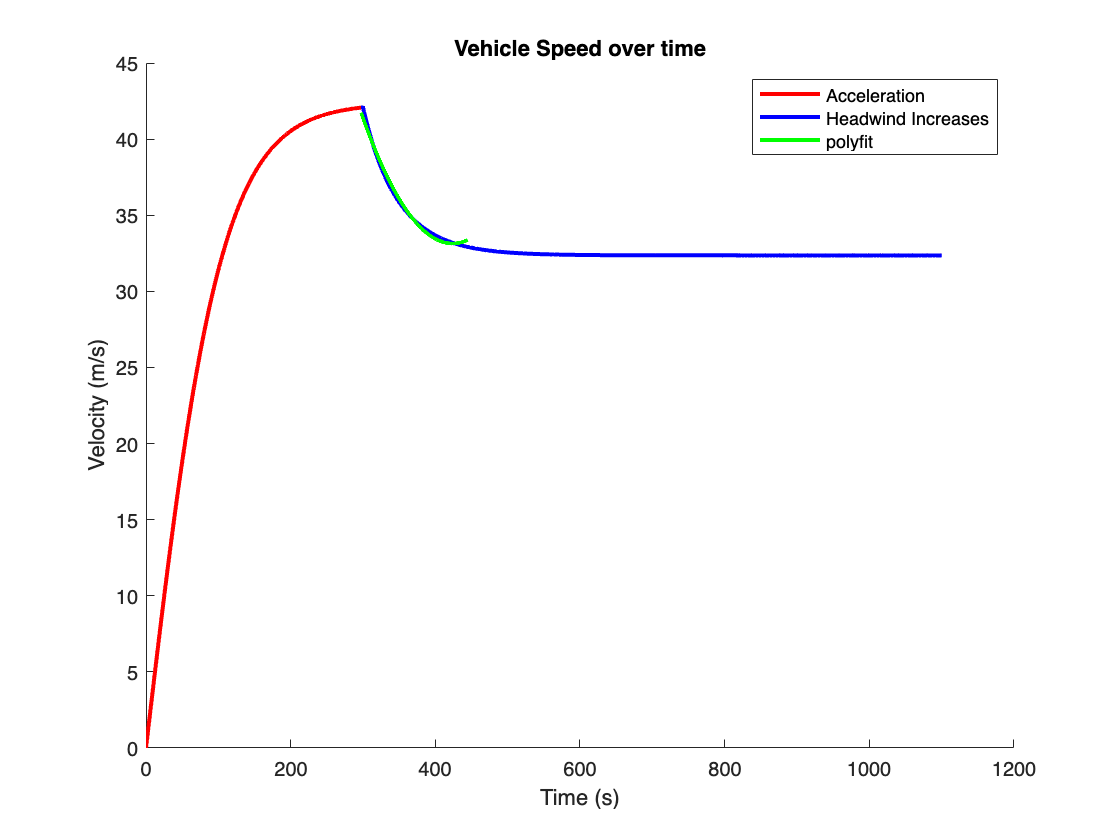

close all, figure
hold on
extractFrom = 108000;
extractTo = 125000;
len = length(time);
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:len),V(extractFrom:len),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('Acceleration','Headwind Increases','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

The polyfit should be moved to only the decreasing velocity portion, but note that this resembles braking strength

Speed Settles, then the road slope increases

close all, figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 0;
motorDecreaseTime = 0;

brakeTime = 0;
breakStrength = 0;

headWindTime = 0;
headWind = 0;

roadSlopeTime = 300;
roadSlope = 5;

% Road slope increases at time = 300 to alpha = 5

% Headwind increases to 10 at time 300

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

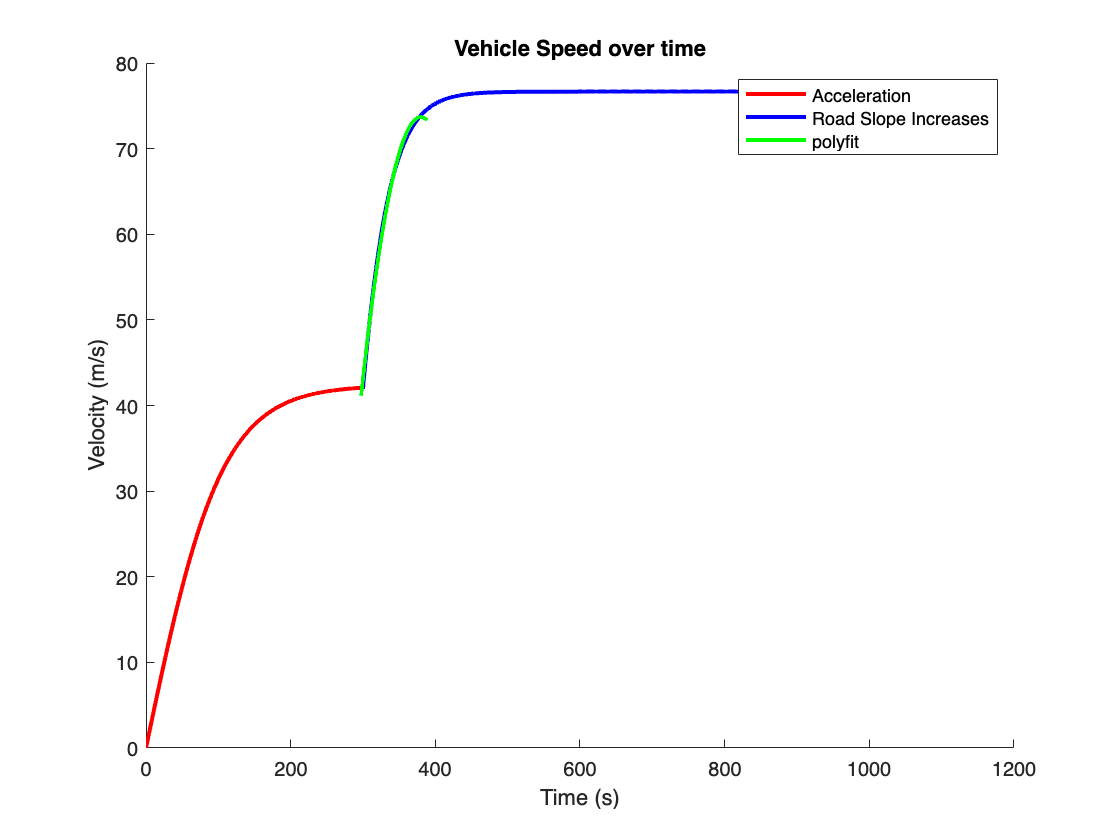

close all, figure
hold on
extractFrom = 108000;
extractTo = 114000;
len = length(time);
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:len),V(extractFrom:len),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('Acceleration','Road Slope Increases','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

# C. Lateral Simulations 

Compute the understeer gradient for the given vehicle and plot the yaw velocity gain versus vehicle speed. Verify that this is an understeer vehicle. *(10 points) *				

Vehicle Parameters are stored in 

%[L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters()
%[L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters()

**Plotting the Vehicle's Yaw Velocity Gain vs speed from the gradient**

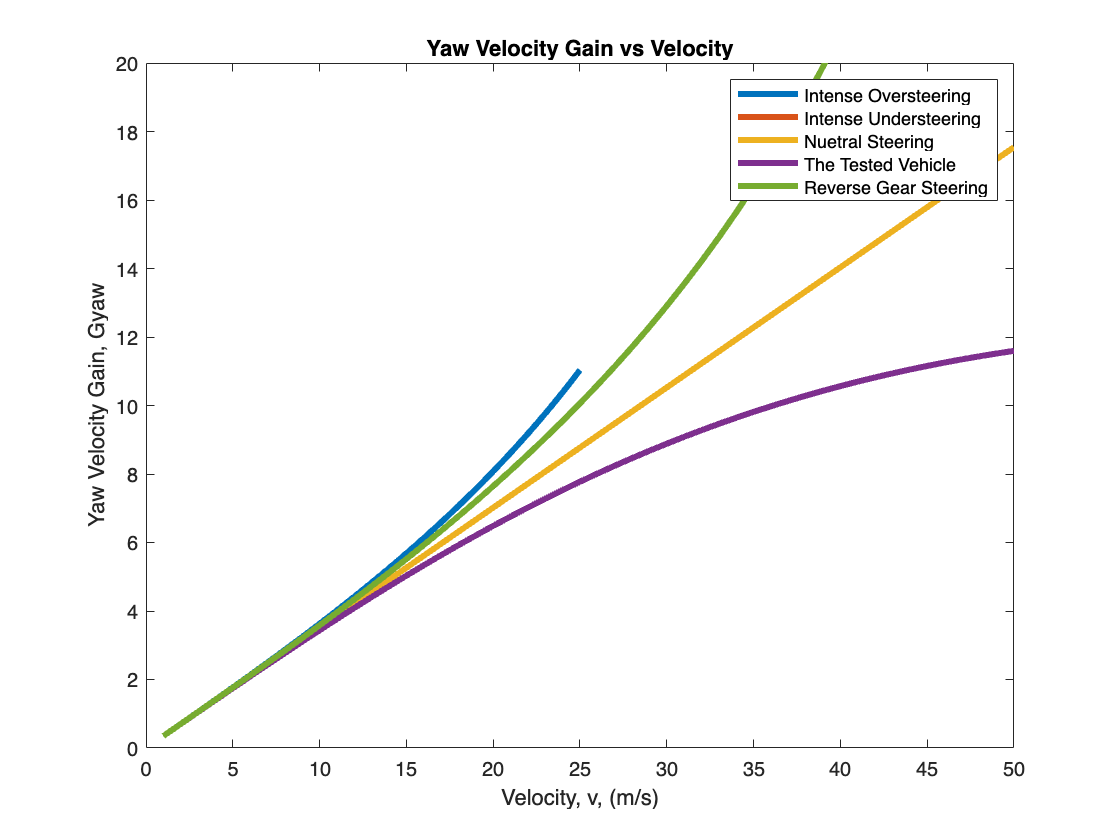

close all, figure
plotUndersteerGradients()

Note that most vehicles are designed to be understeering for ease of control. The test vehicle included. Notice how the reverse gear steering is slightly oversteered, which makes control of reverse gear less intuitive. 

### Lateral Dynamics Simulink Models	

Investigate the nonlinear and linear single-track models provided in same Simulink diagram. 						

[L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters();

The Linear and Nonlienar Lateral models, top level diagram

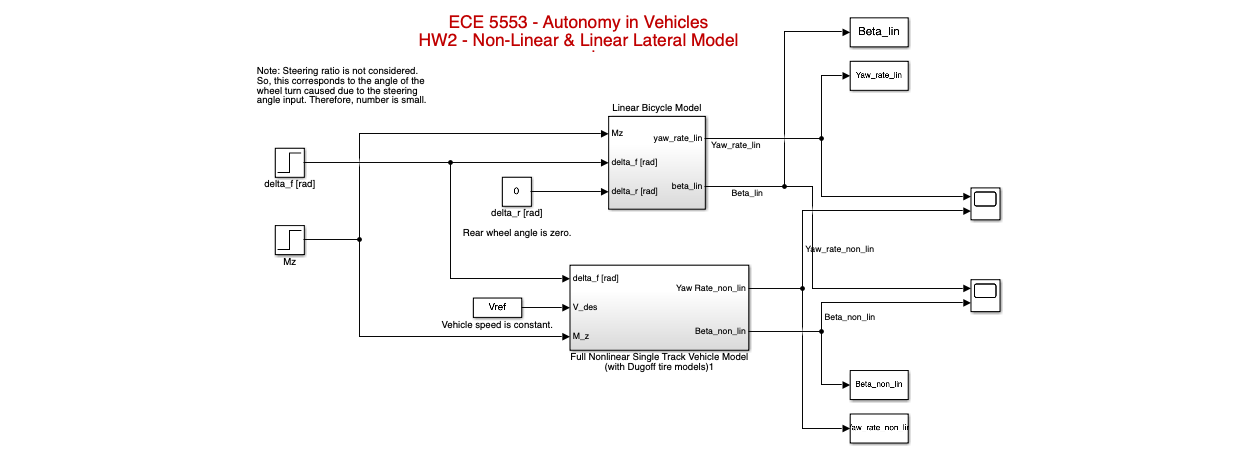

The linear model used is 

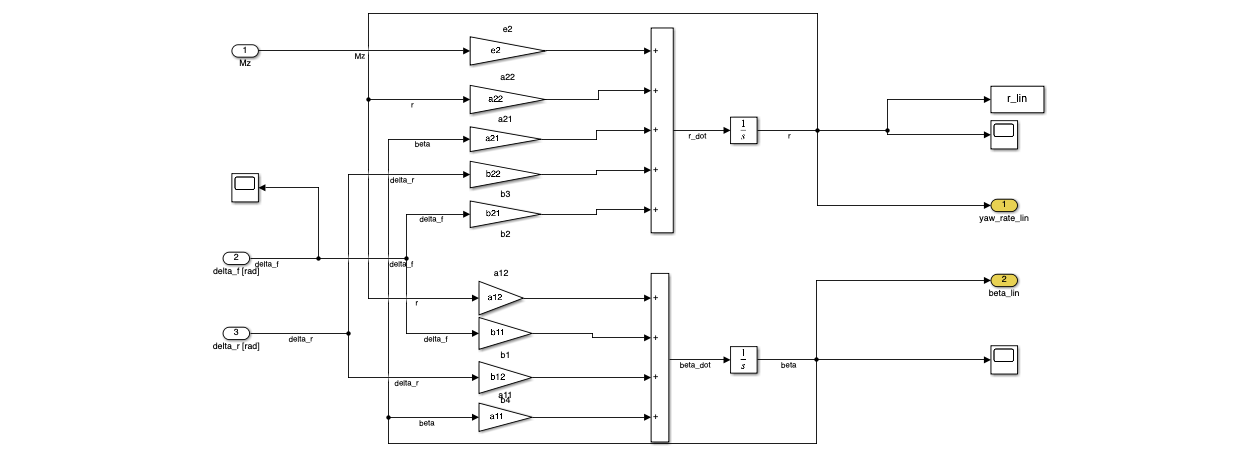

		The nonlinear model used is

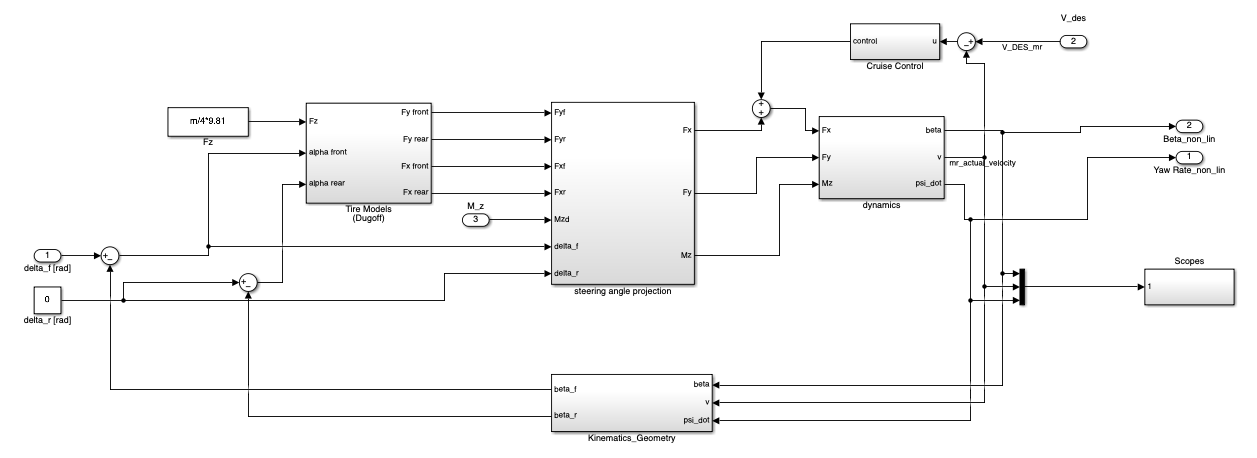

		0				

## Step Steering Input on Lateral Models

Steering Input of 5.7 degrees at 1 second, model comparison 								

Run Simulation 

sim('lateral_models')

Yaw Rate Comparison

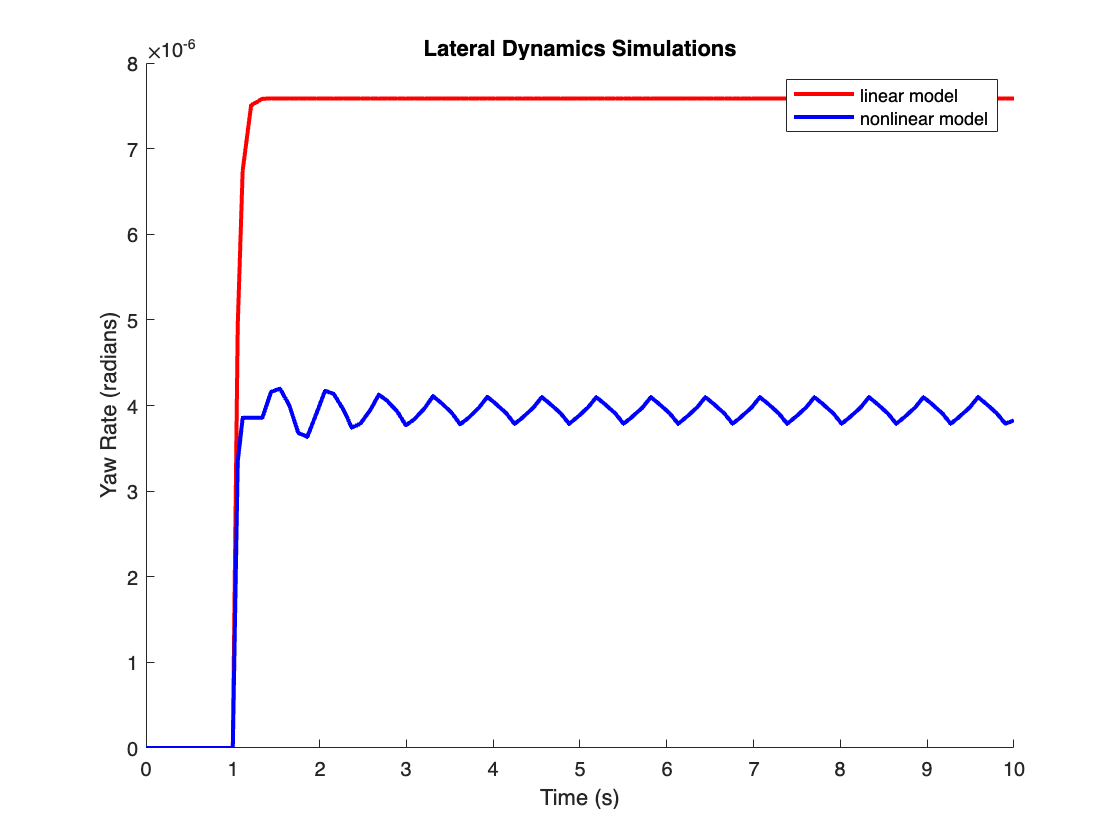

close all, figure, hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians)')

Side Slip angle Comparison 

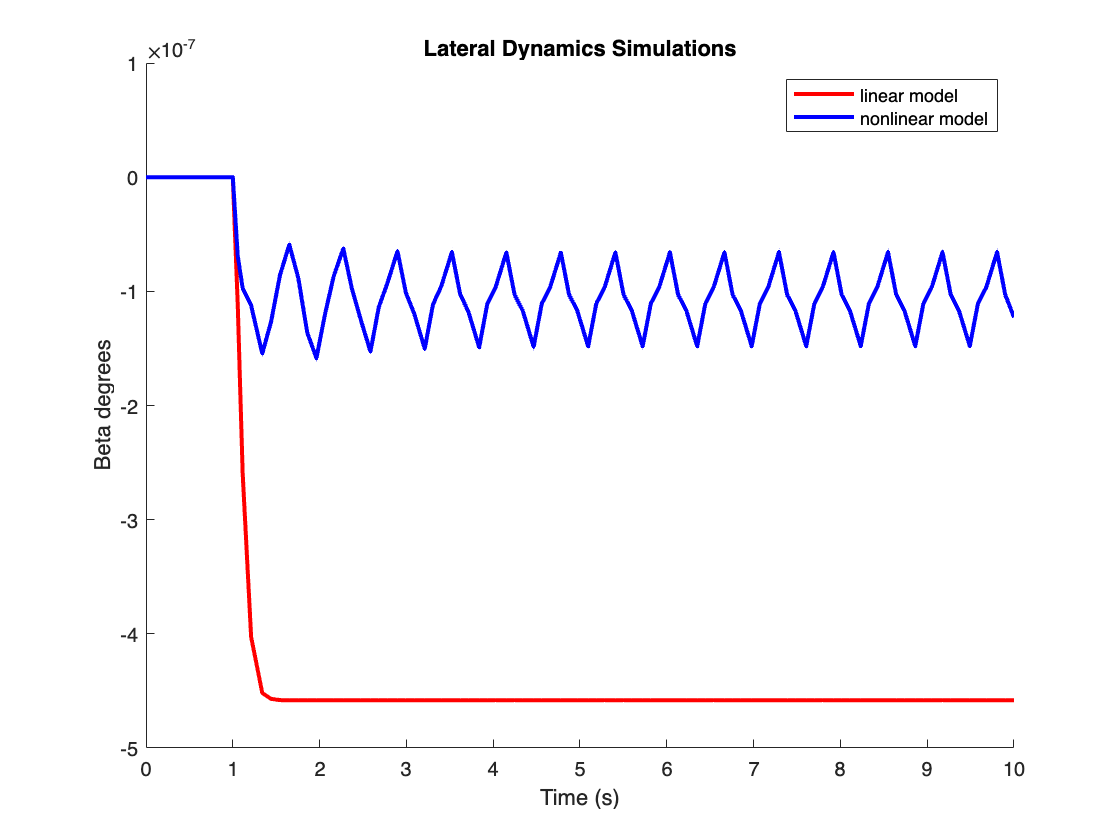

close all, figure, hold on
plot(time,betaLin,'r','linewidth',2)
plot(time,betaNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Beta degrees')

WHY IS IT BETA? 

## Yaw Disturbance comparison

For a Yaw moment disturbance at t = 1

Run Simulation 

sim('lateral_models')

close all, figure, hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians)')

close all, figure, hold on
plot(time,betaLin,'r','linewidth',2)
plot(time,betaNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Beta degrees')

## Functions 

save the simulation output

function vehicle = saveVehicle(Fx,Fy,s,a)
    vehicle.Fx = Fx; % the longitudinal force in the direction of wheel travel
    vehicle.Fy = Fy;
    vehicle.s = s;
    vehicle.a = a;
end 

Retreive Parameters for the longitudinal model

function [M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters()
    M=2000; % Mass of the vehicle[Kg]
    eta_t=0.9; % Transmission Efficiency
    lambda_t=1.0; % Gear Ratio
    lambda_f=4.1; % Final Drive Ratio
    I_w=1; % Inertia of the Wheel[kgm2]
    R_w=0.3; % Wheel Radius[m]
    Meq=0.1*M; % Equivalent Mass Factor
    C_d=0.29; % Drag coefficient
    rho=1.225; % Air density[kg/m3]
    A_f=2.8;% Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.015;%Rolling resistance coefficient
    C_x=3e5; %Longitudinal Stiffness[N]
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    L=2.85;% Wheelbase[m]
    l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
end 

function [M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters()
    %Parameters
    warning off
    M=2000*9.81; % Mass of the vehicle[N]
    eta_t=0.9; %Transmission Efficiency	
    lambda_t=1.0; %Gear Ratio	
    lambda_f=4.1; %Final Drive Ratio	
    I_w=1; %Inertia of the Wheel[kgm2]
    R_w=0.3; %Wheel Radius[m]
    Meq=0.1*M; %Equivalent Mass Factor	
    C_d=0.29; %Drag coefficient 	
    rho=1.225; %Air density[kg/m3]
    A_f=2.8;%Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.015;%Rolling resistance coefficient	
    C_x=3e5; %Longitudinal Stiffness[N]
    L=2.85;%Wheelbase[m]
    l_f=1.3;%Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;%Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_y=1.5e5;%Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;%Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
    Fzf=(l_r*M)/(2*L);% Vertical force for front tire
    Fzr=(l_f*M)/(2*L);% Vertical force for rear tire
end 

function [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters()
    % Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    l_r = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    l_f = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    m = 2000; % Mass of the vehicle [kg]
    Fz = (m*g)/4; % Vertical force is 1/4 on each tire
    
    C_f = 3e5; % Cornering Stiffness of Front Tires
    C_r = 3e5; % Cornering Stiffness of Rear Tires
end 

function [L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters()
    %Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    l_r = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    l_f = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    m = 2000; % Mass of the vehicle [kg]
    Fz = (m*g)/4; % Vertical force is 1/4 on each tire
    
    C_f = 3e5; % Cornering Stiffness of Front Tires
    %Reduced rear cornering stiffness to make Kus < 0;
    C_r = 2e5; % Cornering Stiffness of Rear Tires
end 

function plotUndersteerGradients()
    %Oversteer, Yaw Velocity
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    v_critical = sqrt(-L*g/Kus);
    v = 1:0.5:25; %velocity
    Gyaw_O = v./(L+Kus*v.^2/g);
    plot(v,Gyaw_O,'LineWidth',3), hold on
    
    %Understeer, Yaw Velocity
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    v = 1:1:50; %velocity
    Gyaw_U = v./(L+Kus*v.^2/g);
    plot(v,Gyaw_U,'LineWidth',3)
    
    %Nuetral Vehicle
    Kus_nuetral = 0;
    Gyaw_nuetral = v./(L+Kus_nuetral*v.^2/g);
    plot(v,Gyaw_nuetral,'LineWidth',3)
    
    %The given Vehicle 
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    Gyaw = v./(L+Kus*v.^2/g);
    plot(v,Gyaw,'LineWidth',3)
    
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Cf_r = C_r;
    Cr_r = C_f;
    Lf_r = l_r;
    Lr_r = l_f;
    Kus_reverse = (Lr_r/Cf_r/L - Lf_r/Cr_r/L)*m*g; %static yaw rate gain under steady state conditions (s=0) steering input*Kus = yaw rate, at ss only
    Gyaw = v./(L+Kus_reverse*v.^2/g);
    plot(v,Gyaw,'LineWidth',3)
    xlabel('Velocity, v, (m/s)'),ylabel('Yaw Velocity Gain, Gyaw'),title('Yaw Velocity Gain vs Velocity'), hold on
    legend('Intense Oversteering','Intense Understeering','Nuetral Steering','The Tested Vehicle','Reverse Gear Steering')
    axis([0 50 0 20])
end 

function [L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters()
    %% Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires x2
    Cr = 3e5; % Cornering Stiffness of Rear Tires x2
    Cs = 1.5e5; % Cornering Stiffness
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3; % Wheel radius
    Vref = 20; % Constant vehicle velocity.
    alphaf = 0.1; % Steering wheel angle rad/sec
    %%
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*Vref);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
    b11 = Cf/(m*Vref);
    b12 = Cr/(m*Vref); %delta_r parameter
    b21 = Cf*Lf/J;
    b22 = Cr*Lr/J; %delta_r parameter
    
    e2 = 1/J; % For yaw moment term
end 